# Simulation and Control of Racing Car

### Kasra Sinaei (kks6117@psu.edu)

Fall 2023, The Pennsylvania State University

set(0,'defaultAxesFontName','Times')
set(0,'defaultTextFontName','Times')
set(0,'defaultAxesFontSize',18)
set(0,'defaultTextFontSize',18)
set(0,'defaulttextinterpreter','latex')
set(0,'defaultLineLineWidth',2)
close all; clear; clc;

#### Load an F1 Track

 "Silverstone";

% Loading track data
data = readtable("tracks/"+ans + ".csv");
x_center = data.x_X_m;
y_center = data.y_m;
center_line = [x_center, y_center]';
% Convert Eucledian Coordinate to Curvilinear
refPathObj = referencePathFrenet(center_line'); center_line = refPathObj.SegmentParameters;

#### P Control at constant speed

Select Velocity:

velocity =13;

Select Simulation Duration:

time =5;
% Simulation parameters
dt = 0.05;
deltaT = 0.001;
car = Simulation(center_line, 720, 300, 1.15, 2.3, 100000, deltaT, dt);

time_series = 0:dt:60*time;
y = zeros(3, size(time_series, 1));
output = zeros(6, size(time_series, 1));
input = zeros(2, size(time_series, 1));

K_psi = -0.05;
K_v = 10;

for i = 1:length(time_series)
    u = [K_psi * (car.x_(6)), K_v * (velocity/3.6 - car.x_(1))];
    car = car.step(u);
    y(:, i) = [car.X_; car.Y_; car.psi_];
    output(:, i) = car.x_;
    input(:, i) = u;
    
end

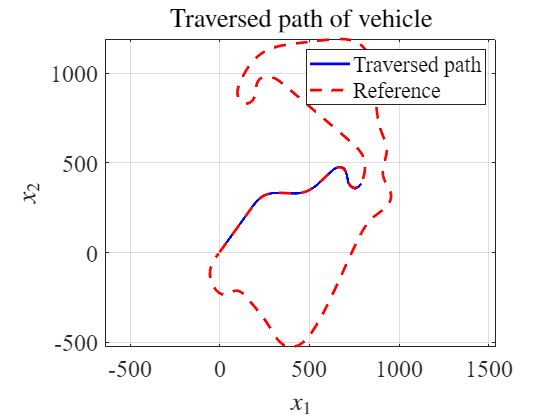

figure
plot(y(1, :), y(2, :), '-b'); hold on; grid on;
plot(center_line(:,1), center_line(:,2), '--r');
legend('Traversed path', 'Reference', Location='northeast')
axis equal
title('Traversed path of vehicle')
xlabel('$x_1$')
ylabel('$x_2$')
grid on

% rectangle('Position',[-20, 825,200,300], EdgeColor='black', LineWidth=2);
% axis equal;
% axes('position',[.6 .3 .15 .3])
% box on % put box around new pair of axes
% index = 160:240; % range of t near perturbation
% index_ = 4462:6500;
% plot(y(1,index_), y(2,index_), '-b'); hold on; 
% plot(center_line(index,1), center_line(index,2), '--r');
% xlim([-100 200])
% ylim([800 1100])
% grid on;axis equal;

#### Linearized System and P Control

Select Velocity:

velocity =13;

Select Simulation Duration:

time =1;
% Simulation parameters
dt = 0.05;
deltaT = 0.001;
% car_hat = Simulation(center_line, 720, 300, 1.15, 2.3, 100000, deltaT, dt);
car = Simulation(center_line, 720, 300, 1.15, 2.3, 100000, deltaT, dt);

time_series = 0:dt:60*time;
% y = zeros(3, size(time_series, 1));
y_hat = zeros(3, size(time_series, 1));
output = zeros(2, size(time_series, 1));

K_psi = -0.05;
K_v = 10;

for i = 2:length(time_series)
    u = [K_psi * (car.x_(6)); K_v * (velocity/3.6 - car.x_(1))];
    [y_hat(:, i), car] = car_hat.stepLinear(u, linear_car.A, linear_car.B);
%     car = car.step(u);
%     y(:, i) = [car.X_; car.Y_; car.psi_];
    
end

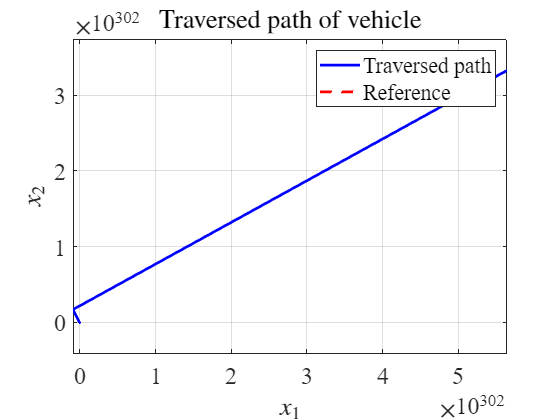

figure
plot(y_hat(1, :), y_hat(2, :), '-b'); hold on; grid on;
plot(y(1, :), y(2, :), '--r');
% plot(center_line(:,1), center_line(:,2), '-.k');
legend('Traversed path', 'Reference', Location='northeast')
axis equal
title('Traversed path of vehicle')
xlabel('$x_1$')
ylabel('$x_2$')
grid on